clear all; 

# Exercise 3.2 - Inverse Kinematic Algorithm

In this exercise you will setup an inverse kinematics algorithm using the pseudoinverse of the jacobian. 

Consider this UR3e robot: 

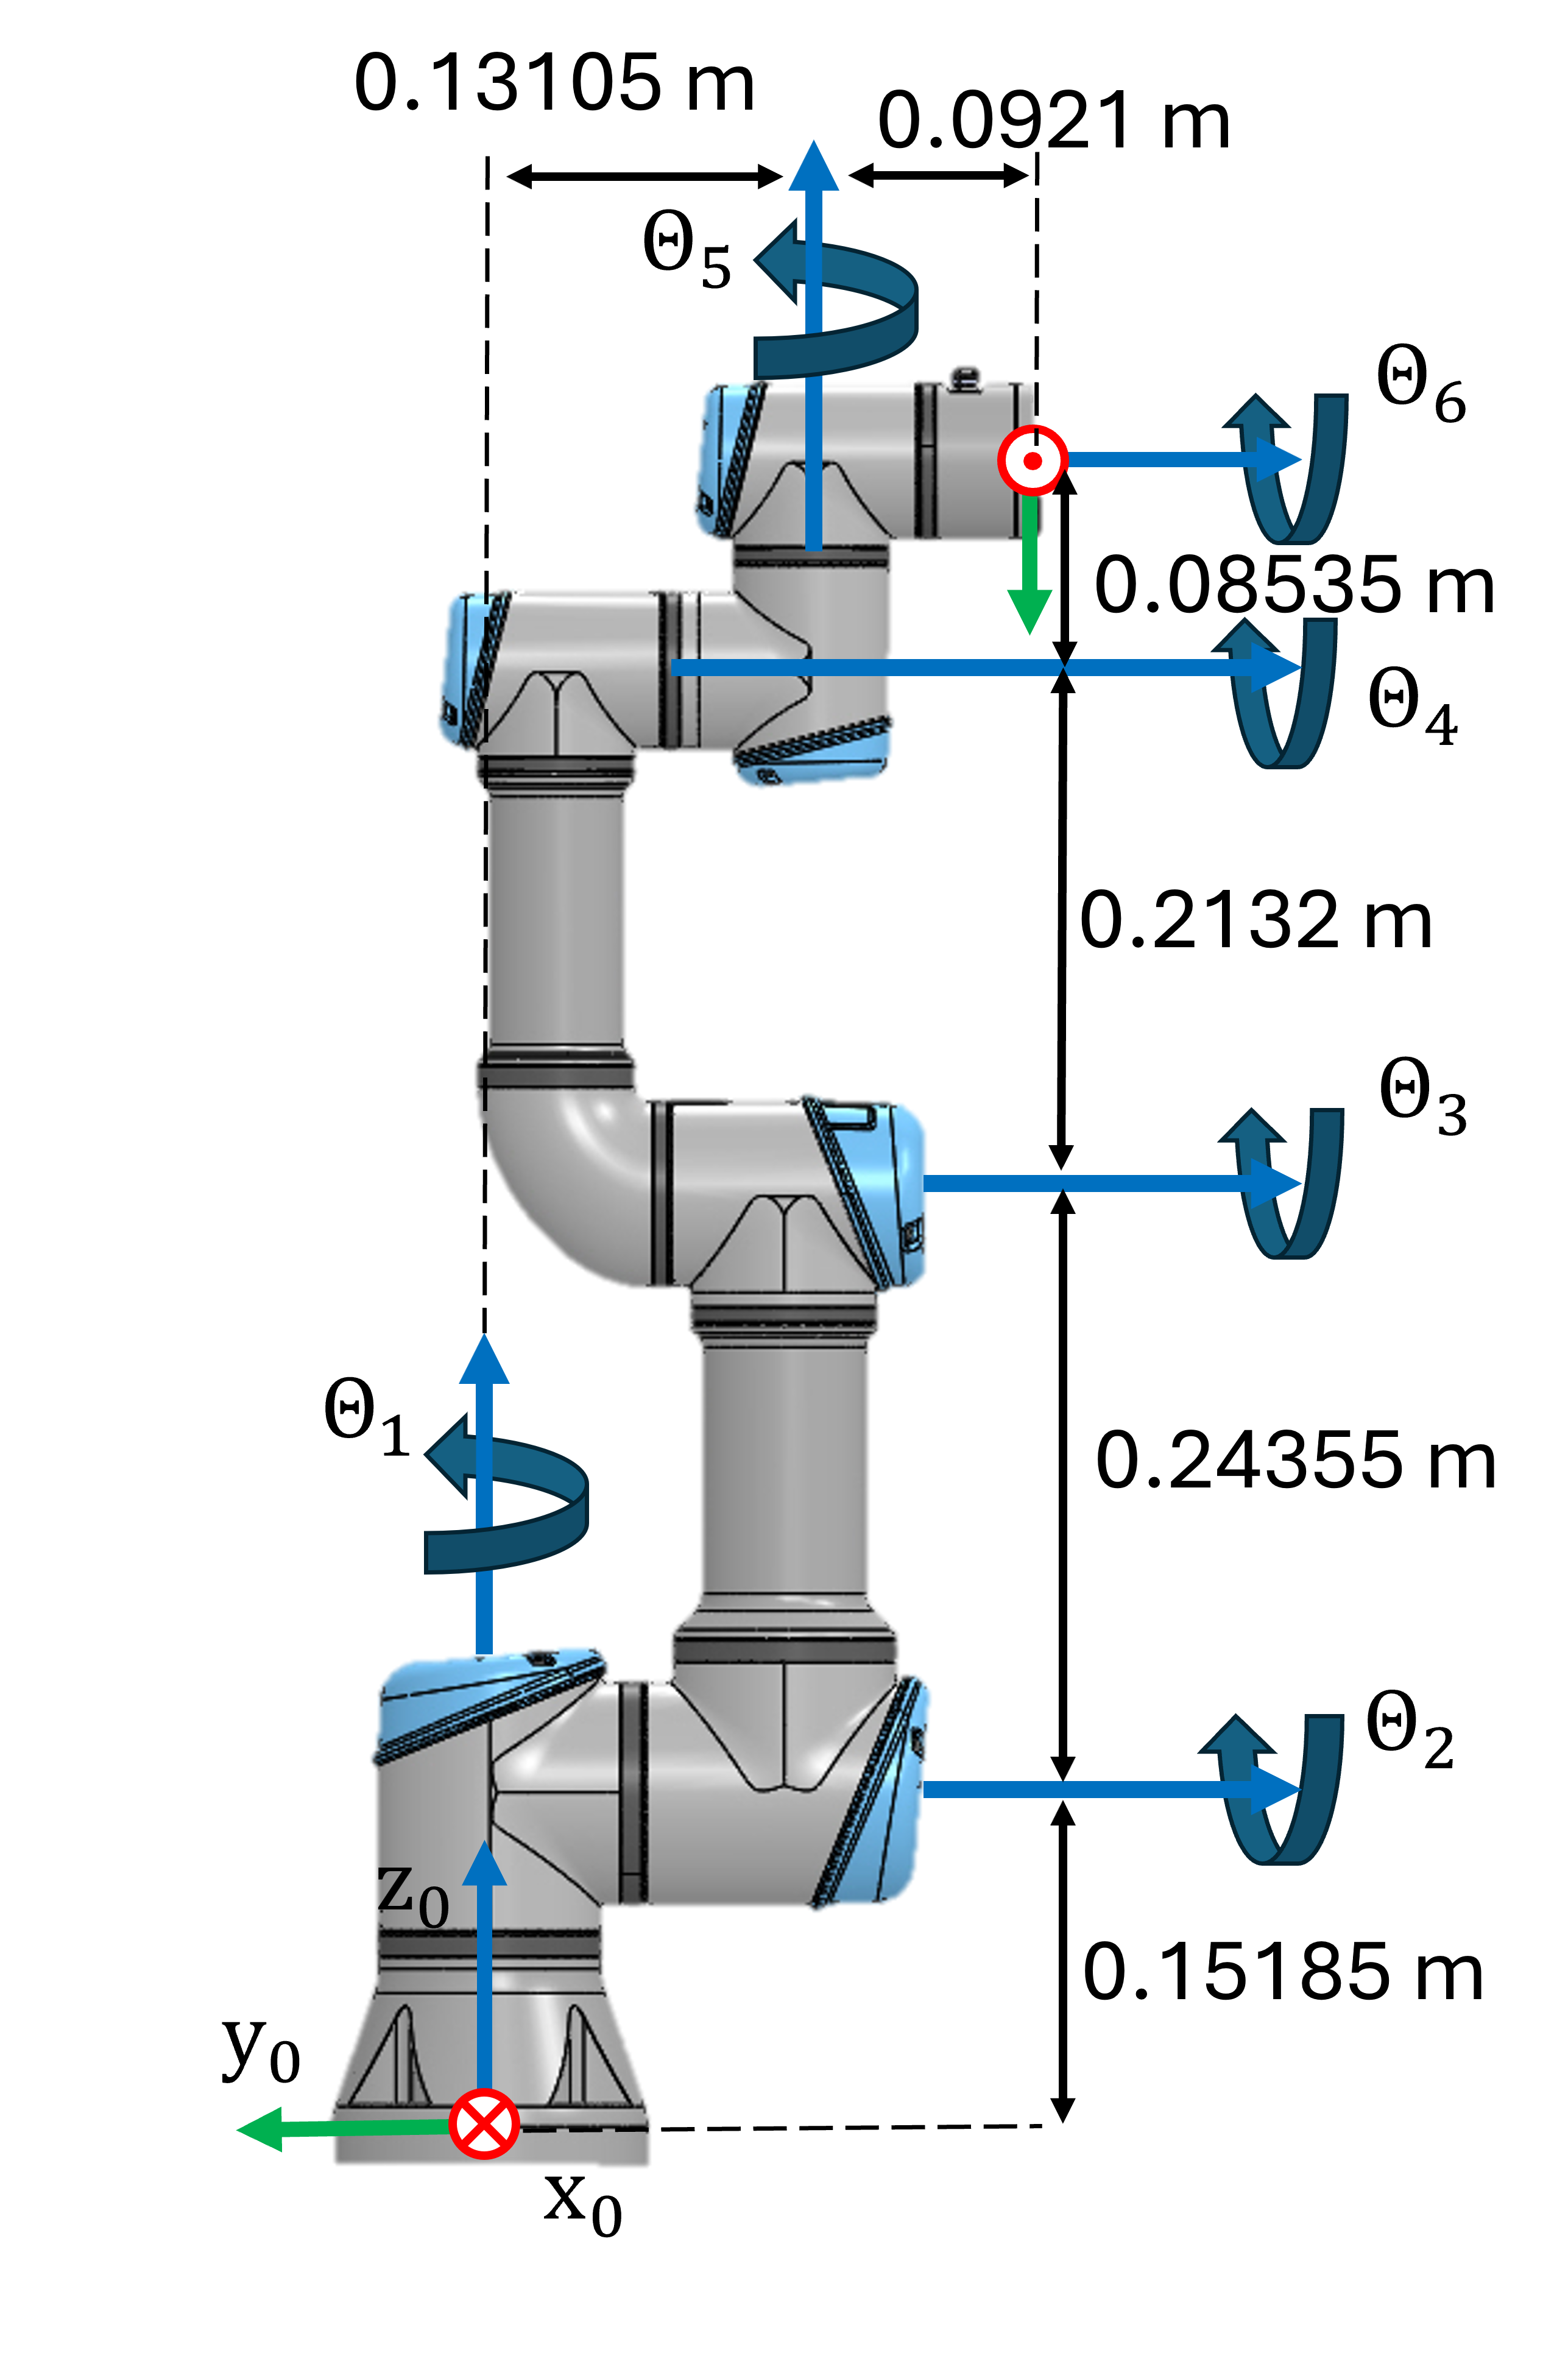

Consider this DH table for the UR3e: 

The control scheme you have to implement is: 

where $k\left(\cdot \right)$ is the forward kinematic of the q. 

## Task 1

Write a function that computes a solution to the inverse kinematic using the pseudoinverse of the Jacobian. The function has the following inputs: 

- the initial joint states as a row vector ($q_0 \in {\mathbb{R}}^{6\textrm{x1}}$)

- desired position vector (only considering cartesian position)$x_{\mathrm{desired}} =\left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack$

- gain (k) 

- tolerance (tol)

- max iterations (Imax)

The function should return the required joint states as a row vector ($q\in {\mathbb{R}}^{6\textrm{x1}}$)

For this task, consider $\dot{x_d } =\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$ and $\Delta t=0\ldotp 01\;s$

Use the following function name for your solution:

-  PseudoInverseAlgorithm(q0, x_desired, k, tol, Imax)

You may use the function below to compute the symbolic transform from the base to the endeffector. 

- dh2tf()

Solve this exercise without using the function: 

- inverseKinematics()


start_time = tic; 
total_iterations = 0;

q0 = [pi/3,-pi/6, pi/3.5,pi/3,-pi/6, pi/3.5]'; 
%x_desired = [0.3, 0.3, 0.3, 0, 0, 0]'; 
x_desired = [0.1, 0.1, 0.1]';
k = 1; 
tol = 1e-3;
Imax = 1000; 
% Call the PseudoInverseAlgorithm to compute joint angles
[q, x_out] = PseudoInverseAlgorithm(q0, x_desired, k, tol, Imax)

q =     1.9328
   -0.3139
    2.7605
   -1.6214
   -1.5990
    0.8976


x_out =     0.0998
    0.0990
    0.1003


total_time = toc(start_time)

total_time = 20.4096

solution_error = x_desired - x_out

solution_error = 1.0e-03 *

    0.1569
    0.9527
   -0.2584


function [q , x] = PseudoInverseAlgorithm(q0, x_desired, k, tol, Imax)

xdot_desired = [0;0;0];
dt = 0.01;

syms q1 q2 q3 q4 q5 q6 real
q_syms = [q1,q2,q3,q4,q5,q6];

DH=[ ...
    0        pi/2        0.15185  q1;
    -0.24355 0           0       q2;
    -0.2132  0           0       q3;
    0        pi/2        0.13105 q4;
    0        -pi/2       0.08535 q5;
    0        0           0.0921  q6];

A06=dh2tf(DH);

p_ee = A06(1:3,4);

Jp = [];

for i=1:6
    Jp = [Jp, diff(p_ee, q_syms(i))];
end

% XYZ Jacobian
Ja_sym = simplify(Jp);      

% XYZ only
x_sym = p_ee;               

q = q0;
i=0;

while i<Imax
    
    Ja = double(subs(Ja_sym, q_syms, q'));
    J_inv = pinv(Ja);
    
    x = double(subs(x_sym, q_syms, q'));
    e = x_desired - x;      

    if norm(e) < tol
        break;
    end
    
    ekd = e*k + xdot_desired;
    
    q_dot = J_inv * ekd;
    
    q = q + q_dot*dt;
    q = mod(q + pi, 2*pi) - pi;
    
    i = i + 1;
end

end

## Task 2

Extend your function from before. 

Add the input: 

- dt (time for discrete algorithm step)

Add the outputs: 

- total_time (time it takes for the algorithm to find a solution)

- total_iterations (iterations until the solution was found)

- solution_error (the pose square error for the solution configuration$\left({\textrm{error}}_{\textrm{solution}} \left(q\right)={e\left(q\right)}^T \cdot e\left(q\right)\right)$)

Use "tic" and "toc" to measure the computational time. 

Use the following function name for your solution:

-  ExtendedPseudoInverseAlgorithm(q0, x_desired, k, dt, tol, Imax, dt)

Solve this exercise without using the function: 

- inverseKinematics()

function [q,total_time,total_iterations,solution_error] = ExtendedPseudoInverseAlgorithm(x_desired, k, dt, tol, Imax, dt)

tic; 
xdot_desired = [0;0;0];

syms q1 q2 q3 q4 q5 q6 real
q_syms = [q1,q2,q3,q4,q5,q6];

DH=[ ...
    0        pi/2        0.15185  q1;
    -0.24355 0           0       q2;
    -0.2132  0           0       q3;
    0        pi/2        0.13105 q4;
    0        -pi/2       0.08535 q5;
    0        0           0.0921  q6];

A06=dh2tf(DH);

p_ee = A06(1:3,4);

Jp = [];

for i=1:6
    Jp = [Jp, diff(p_ee, q_syms(i))];
end

% XYZ Jacobian
Ja_sym = simplify(Jp);      

% XYZ only
x_sym = p_ee;               

q = q0;
i=0;

while i<Imax
    
    Ja = double(subs(Ja_sym, q_syms, q'));
    J_inv = pinv(Ja);
    
    x = double(subs(x_sym, q_syms, q'));
    e = x_desired - x;      

    if norm(e) < tol
        break;
    end
    
    ekd = e*k + xdot_desired;
    
    q_dot = J_inv * ekd;
    
    q = q + q_dot*dt;
    q = mod(q + pi, 2*pi) - pi;
    
    i = i + 1;
end

    
    total_iterations = i;
    total_time = toc; 
    solution_error = e'*e; 

end


Analyze how your algorithm behaves when you change the tolerance, gain or timestep. 